## Information

% MIT IAP Radar Course 2011
% Resource: Build a Small Radar System Capable of Sensing Range, Doppler, 
%  and Synthetic Aperture Radar Imaging 
%
% Gregory L. Charvat
%
% Process Range vs. Time Intensity (RTI) plot
%
% NOTE: set up-ramp sweep from 2-3.2V to stay within ISM band
%  change fstart and fstop bellow when in ISM band

## Preparation and Constant

clear;
close all;
clc;
%%%%% Constants
c = 3E8; %(m/s) speed of light
dBthresh = -55;
minRg = 20;

% Radar Parameter Constants
Tp = 20E-3; %(s) pulse time
fstart = 2225.8E6; % [Hz] LFM start frequency from performance pred. spreadsheet
fstop = 2364.7E6; % [Hz] LFM stop frequency from performance pred. spreadsheet
BW = fstop-fstart; % [Hz] transmtit bandwidth = difference of start and stop freqs
rr = c/(2*BW); % Range Resolution

rangeMovie = 'no';


% Read the raw data .wav file here
% Y contains an N x 2 matrix with the following:
%   Column 1: radar return IF signal
%   Column 2: sync square wave from function generator
% FS contains the sample frequency of the recording software
%   Typically 44100 samples/sec
[Y,FS] = audioread(strcat("./Collections/23-09-Traffic3-02-21-23-R.wav")); % PICK FILE NAME HERE
% Radar parameters
%%%%% ===== Time Between Vertical Steps
N = Tp*FS; % # of samples per pulse
f = linspace(fstart, fstop, N/2); %instantaneous transmit frequency
max_range = rr*N/2; % Max Range    

% Create separate vectors for the IF signal and the sync signal
trig = Y(:,2);
s = Y(:,1);
clear Y;

## ????

% Parse the data here by triggering off rising edge of sync pulse
count = 0;
thresh = 0;
start = (trig > thresh);
for ii = 100:(size(start,1)-N)
    if start(ii) == 1 & mean(start(ii-11:ii-1)) == 0
        count = count + 1;
        sif(count,:) = s(ii:ii+N-1);
        time(count) = ii*1/FS;
    end
end

% Check to see if triggering works
% Ni = 1;
% Nf = 15000;
% plot(trig(Ni:Nf),'.b');
% hold on;
% plot(start(Ni:Nf),'.r');
% hold off;
% grid on;

% Subtract the average
ave = mean(sif,1);
for ii = 1:size(sif,1)
    sif(ii,:) = sif(ii,:) - ave;
end

zpad = 8*N/2;
R = linspace(0,max_range,zpad/2);

## RTI Plots

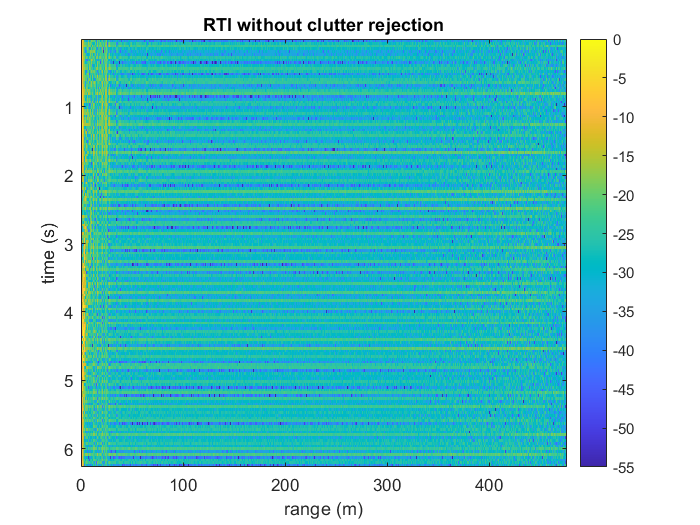

%RTI plot
fig10 = figure(10);
fig10.Renderer = 'Painters'; % this ensures that your figure will be vector/ps
v = dbv(ifft(sif,zpad,2));
S = v(:,1:size(v,2)/2);
m = max(max(v));
S1 = S-m; % RTI only
imagesc(R,time,S1,[dBthresh, 0]);
colorbar;
ylabel('time (s)');
xlabel('range (m)');
title('RTI without clutter rejection');

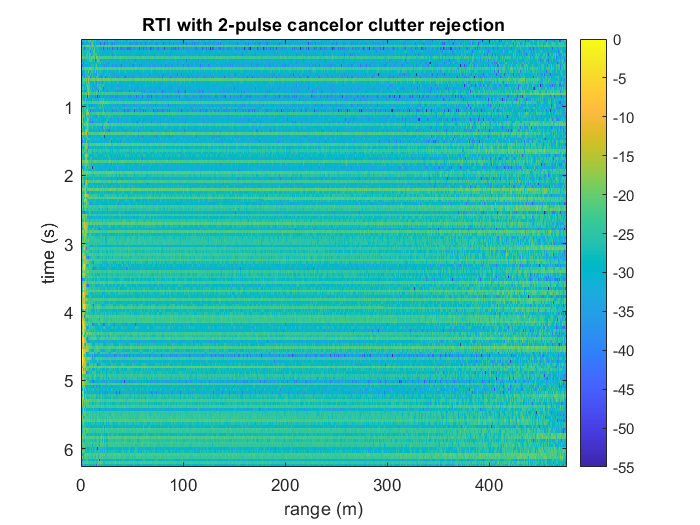


%2 pulse cancelor RTI plot
fig20 = figure(20);
fig20.Renderer = 'Painters'; % this ensures that your figure will be vector/ps
sif2 = sif(2:size(sif,1),:)-sif(1:size(sif,1)-1,:);
v = ifft(sif2,zpad,2);
S=v;
% for ii = 1:size(S,1)
%     S(ii,:) = S(ii,:).*R.^(3/2); %Optional: magnitude scale to range
% end
S = dbv(S(:,1:size(v,2)/2));
m = max(max(S));
S2 = S-m; % RTI with 2 pulse cancellation
imagesc(R,time,S2,[dBthresh, 0]);
colorbar;
ylabel('time (s)');
xlabel('range (m)');
title('RTI with 2-pulse cancelor clutter rejection');

## Hough Transform

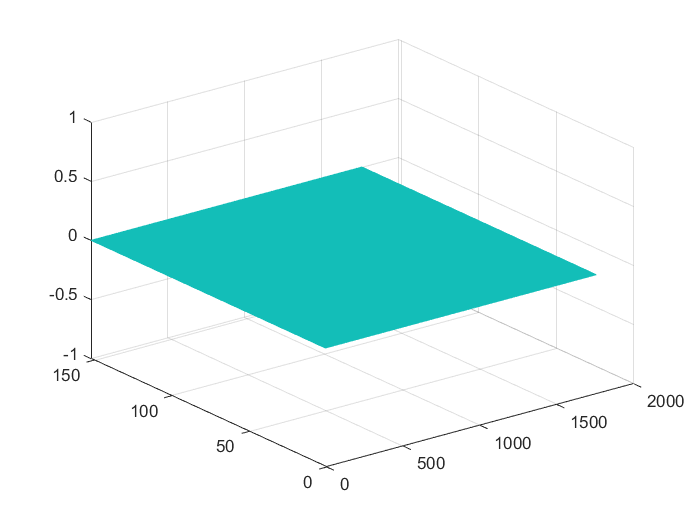

%%% Hough Transform

%% Isolate Main Target

% Thresholding Out Noise
S2 = S2-min(min(S2));
S2 = (S2>=90).*100;
figure(); mesh(S2);

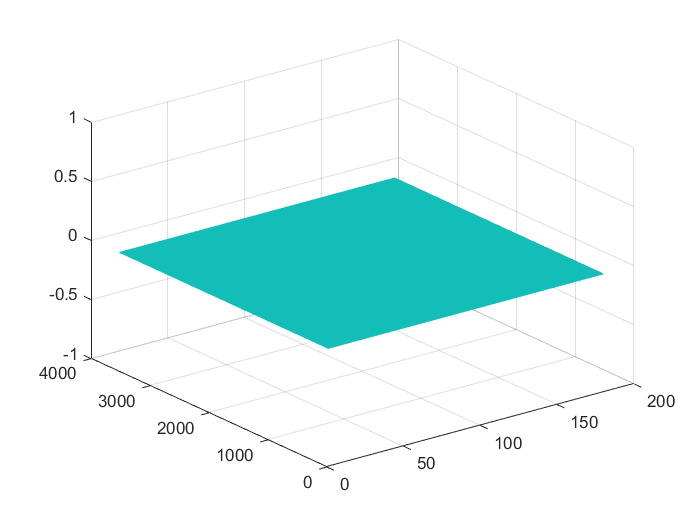


[rows,cols] = size(S2);
transform = hough(S2); % Obtain Hough Transform
figure(); mesh(transform); % Display Hough Transform


[rhoMax, ~] = size(transform);
% Use n Number of Maximums from Hough Transform
%for n = 1:sum(sum(transform>200))
for n = 1:1
    [maxRows, iRows] = max(transform);
    [maxColumns, deg] = max(maxRows);
    
    rho = iRows(deg) - (rhoMax-1)/2.0;
    deg = deg - 90;
    m = -1/tand(deg);
    
    % Draw Hough Line Over Original Image
    for j = 1:cols
        k = m*j + rho/sind(deg);
        if k >= 1 && k <=rows
            S2(round(k),j) = 500;
        end
    end
    
    % Remove Max from Hough Transform to Allow Next One
    a = iRows(deg+90);
    b = deg+90;
    if b-1 <= 0
        c = 1;
    else 
        c = b-1;
    end
    %%% TEMPORARILY DISABLED
    %transform(a-(round(rhoMax*(3/180))):a+(round(rhoMax*(3/180))),c:b+1) = 0;
end

figure(); mesh(transform); % Display (Holes) Hough Transform


% Display Image With Hough Line
figure(); mesh(S2);

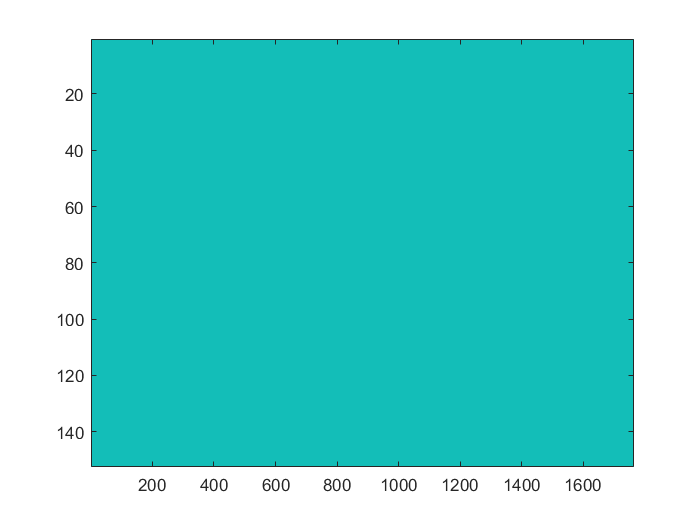


% Attempt to Extract Another?
%     [maxRows, iRows] = max(transform);
%     [maxColumns, deg] = max(maxRows);
%     rho = iRows(deg) - (rhoMax-1)/2.0;
%         transform(iRows(deg+90),deg+90) = -50;
%     deg = deg - 90;
%     m = -1/tand(deg);
%     for i = 1:rows
%         j = m*i + rho/sind(deg);
%         if j < 1
%             j = 1;
%         end
%         S(i,round(j)) = -10;
%     end
figure(); imagesc(S2);

## Velocity Calculation

%% Velocity Calculation

velocity = m * ( (max(time)/rows) / (max(R)/cols) );
fprintf('Velocity: %0.4f m/s\n',velocity);

Velocity: 0.0027 m/s


fprintf('Velocity: %0.4f mph\n\n',velocity/2.23694);

Velocity: 0.0012 mph




% figure(25);
% plotminR = 20; % meters
% plotmaxR = 120; % meters
% delR = max_range/zpad;
% Rzoom = linspace(plotminR,plotmaxR,floor((plotmaxR-plotminR)/delR));
% imagesc(Rzoom,time,S2(:,floor(plotminR/delR):floor(plotmaxR/delR)),[dBthresh, 0]);
% colorbar;
% ylabel('time (s)');
% xlabel('range (m)');
% title('Zoomed RTI with 2-pulse cancelor clutter rejection');

%% Plot single time slice
% figure;
% [Rw,Cl]=size(S0);
% width = 150;
% figure
% for ii=1:Rw
%     plot(S0(ii,1:width))
%     axis([0,width,-150,0])
%     pause(0.04)
% end
% %2 pulse mag only cancelor
% figure(30);
% clear v;
% for ii = 1:size(sif,1)-1
%     v1 = abs(ifft(sif(ii,:),zpad));
%     v2 = abs(ifft(sif(ii+1,:),zpad));
%     v(ii,:) = v2-v1;
% end
% S=v;
% R = linspace(0,max_range,zpad);
% for ii = 1:size(S,1)
%     S(ii,:) = S(ii,:).*R.^(3/2); %Optional: magnitude scale to range
% end
% S = dbv(S(:,1:size(v,2)/2));
% m = max(max(S));
% imagesc(R,time,S-m,[-20, 0]);
% colorbar;
% ylabel('time (s)');
% xlabel('range (m)');
% title('RTI with 2-pulse mag only cancelor clutter rejection');
